# Kepler轨道预测

基于Matlab R2020a

## 相关常数的定义

Vx = 8e03; Vy = 0.5e03; Vz = 2e03; %示例采用xoy平面内的第一宇宙速度近地轨道
Rx = 0; Ry = 1.2*6.371e06; Rz = 0;%均为惯性坐标系下的投影分量，采用国际单位制
V0 = [Vx;Vy;Vz];
R0 = [Rx;Ry;Rz]; %列向量
mu = 398603e09; 

## 将速度与坐标分量转换为轨道根数

[a0,e0,theta0,Omega0,i0,omega0] = pro2orb(V0,R0); %pro2ob()函数为自定义的函数，见pro2orb.mlx文件

## 轨道要素预报：

T = 2*pi*sqrt(a0^3/mu);
t_list = 0:0.01*T:T;
a = zeros(1,size(t_list,2))+a0; 
e = zeros(1,size(t_list,2))+e0; 
Omega = zeros(1,size(t_list,2))+Omega0;
i = zeros(1,size(t_list,2))+i0; 
omega = zeros(1,size(t_list,2))+omega0;
tic
theta = predict_kepler(a0,e0,theta0,t_list);%利用当前轨道根数，预测新的轨道根数，predict()函数为自定义的函数，见predict.mlx文件
[V,R] = orb2pro(a,e,theta,Omega,i,omega);%将新的轨道根数转化为分量形式，orb2pro()函数为自定义的函数，见orb2pro.mlx文件
toc

历时 0.122997 秒。


## 绘制Kepler轨道位置

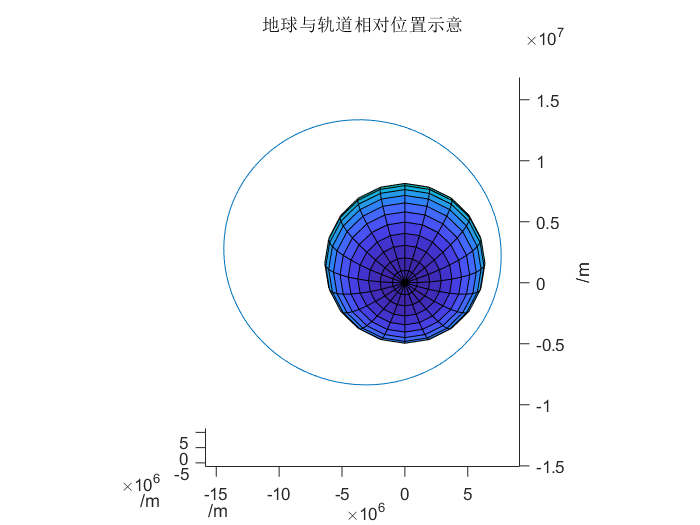

figure
hold on
plot3(R(1,:),R(2,:),R(3,:));
ellipsoid(0,0,0,6.371e06,6.371e06,6.371e06);
view(cross(R(:,1),V(:,1)))
axis equal
title('地球与轨道相对位置示意')
xlabel('/m');
ylabel('/m');
zlabel('/m');
hold off

## 绘制速度随时间的变化关系

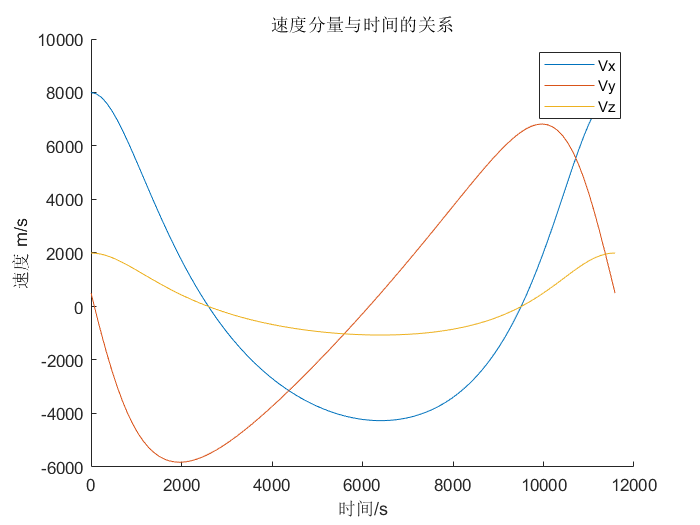

figure
hold on;
plot(t_list,V(1,:));
plot(t_list,V(2,:));
plot(t_list,V(3,:));
legend('Vx','Vy','Vz');
xlabel('时间/s');
ylabel('速度 m/s');
title('速度分量与时间的关系')
hold off

## 绘制位置随时间的变化关系

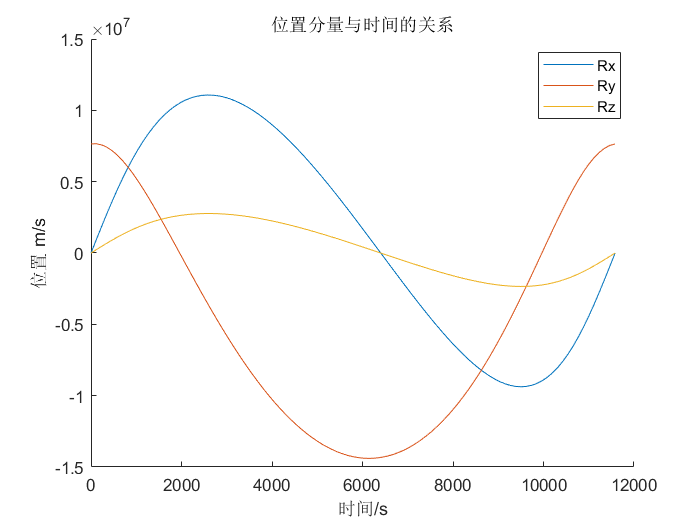

figure
hold on;
plot(t_list,R(1,:));
plot(t_list,R(2,:));
plot(t_list,R(3,:));
legend('Rx','Ry','Rz');
xlabel('时间/s');
ylabel('位置 m/s');
title('位置分量与时间的关系')
hold off